# Actividad #11

**Machine Learning Roadmap, Data Forecasting**

- Nombre 1:

- Nombre 2:

- Nombre 3:

- Fecha:

- Reposiroty: [https://github.com/vasanza/SSE](https://github.com/vasanza/SSE)

- Refrence: [https://github.com/vasanza/Matlab_Code/tree/main](https://github.com/vasanza/Matlab_Code/tree/main)

- Dataset: [Open Energy Data Initiative (OEDI)](https://data.openei.org/)

- [Photovoltaic Data Acquisition (PVDAQ) Public Datasets](https://data.openei.org/s3_viewer?bucket=oedi-data-lake&prefix=pvdaq%2F2023-solar-data-prize%2F2105_OEDI%2Fdata%2F)

## Descripción:

##  Objetivos:

Raw data

- Enfocarnos en la prediccion de datos "**Data Forecasting**"

- Determinar el periodo de tiempo que se desea hacer forecasting

- Determinar las variables de entrada (input) y de salida (output) de un sistema de caja negra

Preprocessing

- Remover valores NAN, outlier (hampel filter), etc.

Feature Extraction

- Variables or caracteristicas estadisticos en el tiempo de esas variables

Otros

- Utilizar matriz de correlacion para eliminar variables o caracteristicas redundantes

- Dividir el data en 70% (training_data) y 30% (testing_data)

- Utilizar el toolbox **"regressionLearner"** de Matlab

- Seleccionar el mejor modelo de Data Forecasting basado en el RMSE

- Utilizar el mejor modelo para hacer el testing en el codigo principal (main)

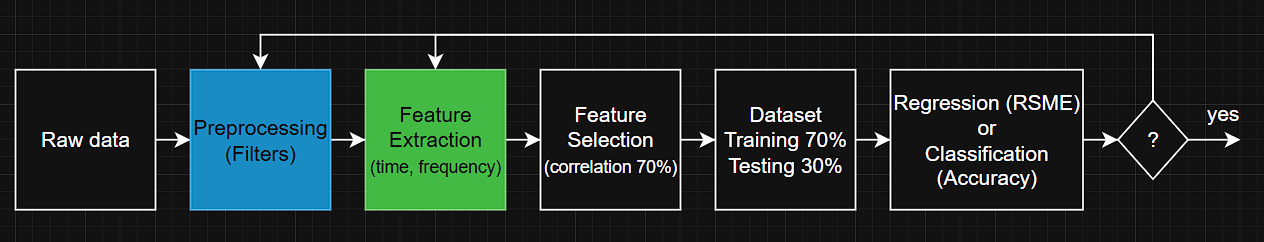

## Tipo de Dataset a utilizar:

- Cada columna representa una variable y cada fila representa una muestra (frecuencia de mestreo constante)

- La primera columna es el TimeStamp. Ejemplo: 'dd-MMM-yyyy HH:mm:ss.SSS'

- El arhivo debe estar en formato **.csv**, si es otro formato de debera convertir a .csv. Ejemplo: si es **.parqet**, se lo convierte con esta pagina [https://table.studio/convert/parquet/to/csv](https://table.studio/convert/parquet/to/csv)

- Si existen multiples archivos .csv, estos se deberan colocar en la carpeta data, siempre que esten relacionadas a un mismo sistema. **Ejemplo de regresion**: consumo_enero_2025.csv, consumo_febrero_2025.csv, etc. **Ejemplo de clasificacion**: consumo_casa_enero_2025.csv, sonsumo_escuela_enero_2025.csv, etc.

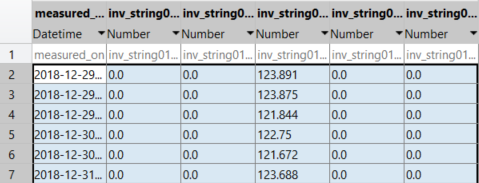

## **Copia la actividad en tu respaldo**

%Configuracion de carpeta ./src para librerias
addpath(genpath('./src'));

% Definir rutas
miRespaldo = 'C:\Desktop\SSE_vic';  %<========
repositorio = 'C:\Desktop\SSE\2025';%<========

if true

filename = struct with fields:
       name: '2105_inv01_data.csv'
     folder: 'C:\Users\victo\Desktop\SSE\2025\ACTIVIDAD11\data'
       date: '20-Jun-2025 19:15:47'
      bytes: 18694812
      isdir: 0
    datenum: 7.3979e+05


    % repositorio -> respaldo

maxFiles = 1

    git_sse(miRespaldo)
else
    % Mombre de la carpeta de la Actividad en el repositorio
    nombreCarpeta = string(split(cd, filesep));
    nombreCarpeta = nombreCarpeta(end) % Nombre de la carpeta
    % Regresar al repositorio
    cd(fullfile(repositorio,nombreCarpeta))
end

## Desarrollo de la Actividad

#### Configuración de carpeta ./src para librerias y  ./data para el raw data

clear % Borrar variables en el workspace y libera memoria RAM
clc % Limpia el Command Window
addpath(genpath('./src')); %librerias
datapath = fullfile('./data/');%raw data

# Paso 1: Raw Data

**Buscar nombres de archivos .csv en ./data**

filename = FindCSV(datapath)
maxFiles = size(filename,1)

#### Cargar automaticamente todos los archivos csv desde ./data

allData = [];

ans =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {1×6 cell}
    VariableDescriptions: {1×6 cell}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


for i=1:maxFiles
    nameFile = filename(i).name;
    pathFile = strcat(datapath, nameFile);
    rawData = fLoad_dataset(pathFile);
    allData = [allData; rawData];

VariableNames = 6×1 cell array
    {'measured_on'                                     }
    {'inv_string01_ac_output__kwh__inv_150164'         }
    {'inv_string01_ac_output__power_factor__inv_150165'}
    {'inv_string01_ac_voltage__v__inv_150163'          }
    {'inv_string01_dc_voltage__v__inv_150162'          }
    {'inv_string01_temperature__c__inv_150166'         }


end
clear rawData nameFile filename; 


ans = 4×6 table
        measured_on        inv_string01_ac_output__kwh__inv_150164    inv_string01_ac_output__power_factor__inv_150165    inv_string01_ac_voltage__v__inv_150163    inv_string01_dc_voltage__v__inv_150162    inv_string01_temperature__c__inv_150166
    ___________________    _______________________________________    ________________________________________________    ______________________________________    ______________________________________    _______________________________________

    2019-02-12 10:59:00                         0                                            0                                            121.75                                    450.75                                     40.46                 
    2019-02-12 11:14:00                  

%Seleccionar cuantas muestras queremos usar en esta actividad
maxSamples = size(allData,1);
samples = 8760;
%Visualizar propiedad de los archivos CSV
allData.Properties

**Extraer y graficar las variables**

% Extraer el TimeStamp
t = datetime(allData.measured_on);
% Extraer el resto de variables
VariableNames = allData.Properties.VariableNames'

**Identificar el periodo de muestreo del Raw Data**

% Revisar el dataset
allData(1:4,:) %el periodo de sampleo es (15min)
%para hacer forecasting, definir un tiempo o step de prediccion
step = 4; %Representa un tiempo de prediccion (15min x step = 1h)

**Inputs_Variables**

% inv_string01_ac_output__kwh__inv_150164
pw_in = allData{:,VariableNames(2)}; % Variable de la columan 2
pw_in = pw_in(1:samples - step); % Limitar el numero de muestras

% inv_string01_ac_output__power_factor__inv_150165
pf_in = allData{:,VariableNames(3)};% Variable de la columan 3
pf_in = pf_in(1:samples - step); % Limitar el numero de muestras

% inv_string01_ac_voltage__v__inv_150163
vac_in = allData{:,VariableNames(4)};% Variable de la columan 4
vac_in = vac_in(1:samples - step); % Limitar el numero de muestras

% inv_string01_dc_voltage__v__inv_150162
vdc_in = allData{:,VariableNames(5)};% Variable de la columan 5
vdc_in = vdc_in(1:samples - step); % Limitar el numero de muestras

% inv_string01_temperature__c__inv_150166
temp_in = allData{:,VariableNames(6)};% Variable de la columan 6
temp_in = temp_in(1:samples - step); % Limitar el numero de muestras

**Ouput_Variable**

% Aqui se debe poner la variable de salida, si viniera en el Dataset
% Pero en este ejemplo, se lo genera al desfasar step muestras a la ravible pw_in

**Raw data [Inputs_Variables Output_Variables]**

% Raw data [Inputs_Variables Output_Variables]
rawdata = [pw_in pf_in vac_in vdc_in temp_in];
clear pw_in pf_in vac_in vdc_in temp_in

# Paso 2: Preprocessing

**Eliminar NAN**

rawdata(isnan(rawdata)) = 0;  % eliminar todos los "not a number"

**Eliminar outliers**

preData = hampel(rawdata);

**Graficar Raw data vs datos preprocesados**

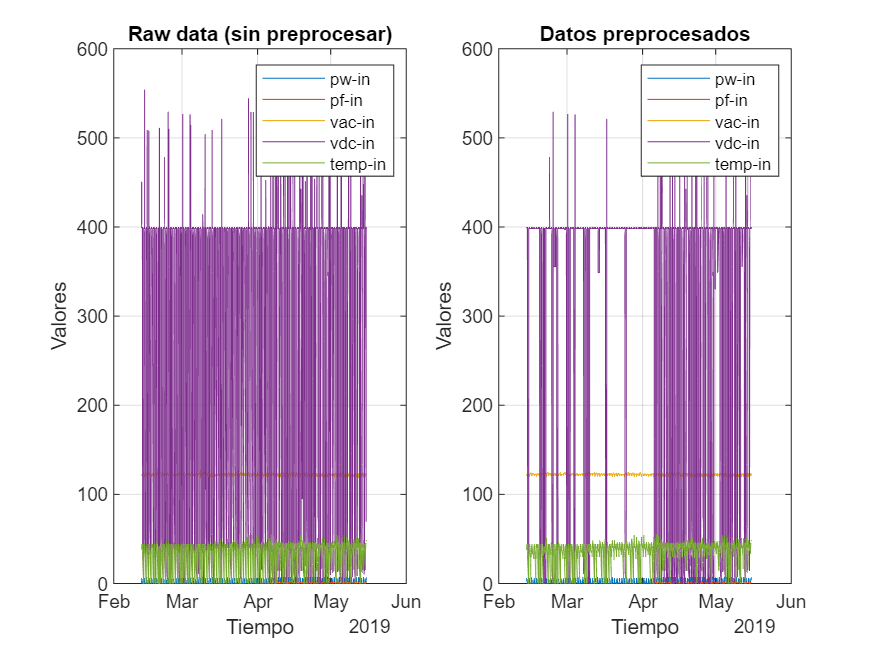

figure;

subplot(1,2,1)
% Graficar raw data
plot(t(1:samples - step,:),rawdata); % las 1k primeras filas
legend("pw-in", "pf-in", "vac-in", "vdc-in", "temp-in");
xlabel('Tiempo');
ylabel('Valores');
title('Raw data (sin preprocesar)');
grid on;

subplot(1,2,2)
% Graficar raw data
plot(t(1:samples - step,:),preData); % las 1k primeras filas
legend("pw-in", "pf-in", "vac-in", "vdc-in", "temp-in");

xlabel('Tiempo');
ylabel('Valores');
title('Datos preprocesados');
grid on;

# Paso 3: Feature extraction

DataIn=[];
for i=1:step:size(preData,1)-(step-1)
    feat = [mean(preData(i:i+step-1,:),1)];   %<=== mean features
    DataIn=[DataIn;feat];
end

**Output_Variables**

pw_predict = DataIn(2:end,1);
DataIn = [DataIn(1:end - 1, :)];
clear feat

# Paso 4: Feture Selection

%Maximum correlation value allowed
% Dafault 0.70
threshold = 0.5;

% El numero de variables a analizar debe ser igual al numero de nombres de

ans =     1.0000    0.2088   -0.3328    0.2701    0.5630
    0.2088    1.0000   -0.3271    0.2273    0.3404
   -0.3328   -0.3271    1.0000   -0.3030   -0.4167
    0.2701    0.2273   -0.3030    1.0000    0.3421
    0.5630    0.3404   -0.4167    0.3421    1.0000


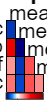

NewDataFeatures =     4.0635         0  121.9491  399.0312
    4.8765         0  122.1405  398.9842
    5.2015         0  121.5275  398.6877
    4.7215         0  120.6757  398.6880
    3.3708         0  120.7853  398.9222
    2.7700         0  121.3435  398.9847
    1.3272         0  122.1560  398.7970
    0.0965         0  122.4882  306.5938
    0.0395         0  122.9727  140.7343
    0.4273         0  122.4963  398.6565


NewFeaturesLabels = 1×4 cell array
    {'mean_pw'}    {'mean_pf'}    {'mean_vac'}    {'mean_vdc'}


LabelsRemove = 1×1 cell array
    {'mean_temp'}


% variables
varNames = {'mean_pw', 'mean_pf', 'mean_vac', 'mean_vdc', 'mean_temp'}; %<=== mean features


Features_labels=varNames;
corrcoef(DataIn)

[NewDataFeatures,NewFeaturesLabels,LabelsRemove] = Feature_Selection(DataIn,Features_labels,threshold)

# Paso 5: Dataset

#### Dividir el dataset en training_data y testing_data

training_data = [NewDataFeatures(1:round(end*0.7),:) ...
    pw_predict(1:round(end*0.7),:)]; % 70% de datos para entrenar
testing_data = [NewDataFeatures(round(end*0.7):end,:) ...
    pw_predict(round(end*0.7):end,:)];% 30% de datos para testing

# Paso 6: Utilizar el toolbox **"regressionLearner"**

regressionLearner

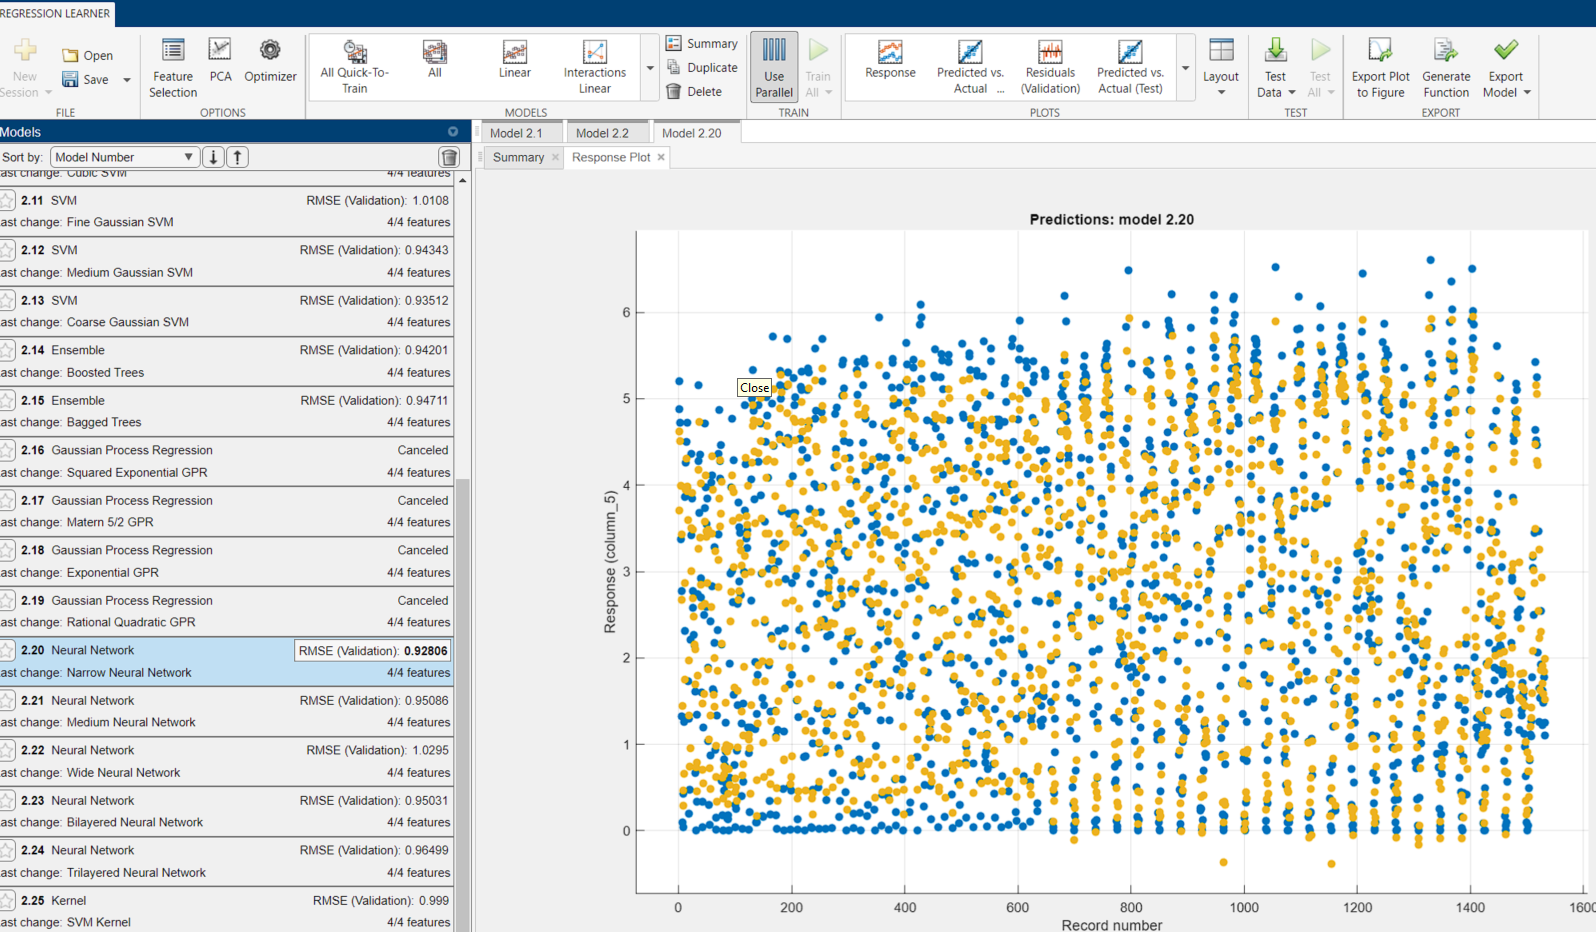

# Paso 7: Hacer testing del modelo de forecasting

Simpre que el numero de features no cmabie, podemos usar esta misma funcion

[trainedModel, validationRMSE] = trainRegressionModel_narrow_NN(training_data)

trainedModel = struct with fields:
                 predictFcn: @(x)neuralNetworkPredictFcn(predictorExtractionFcn(x))
    RegressionNeuralNetwork: [1×1 RegressionNeuralNetwork]
                      About: 'This struct is a trained model exported from Regression Learner R2022a.'
               HowToPredict: 'To make predictions on a new predictor column matrix, X, use: ↵  yfit = c.predictFcn(X) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵X must contain exactly 4 columns because this model was trained using 4 predictors. ↵X must contain only predictor columns in exactly the same order and format as your training ↵data. Do not include the response column or any columns you did not import into the app. ↵ ↵For more information, see How to predict using an exported model.'


validationRMSE = 0.9275


% hacer que el modelo haga la prediccion de pw
y_est = trainedModel.predictFcn(testing_data(:,1:end-1));
y_real = testing_data(:,end);
rmse = sqrt(mean((y_real - y_est).^2))

rmse = 0.8085

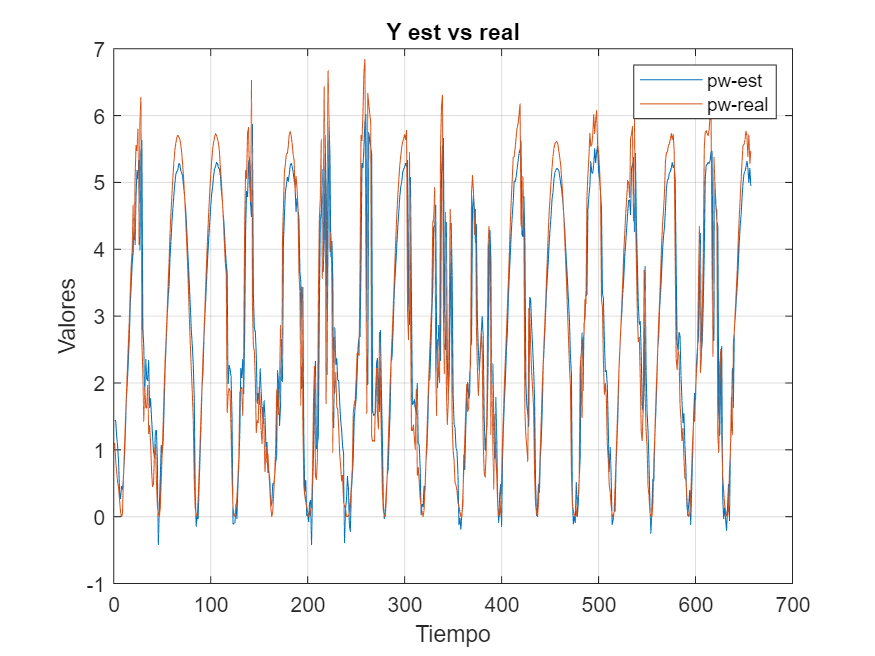


figure;
% Graficar testing del forecasting
plot(y_est); % las 1k primeras filas
hold on
plot(y_real); % las 1k primeras filas
hold off
legend("pw-est", "pw-real");
xlabel('Tiempo');
ylabel('Valores');
title('Y est vs real');
grid on;